#### Example setup: stratification profiles and model initialization

This example demonstrates how to initialize the  InternalGravityWaveSpectrum class using different stratification profiles:

1) Idealized exponential stratification

2) Ocean Station PAPA (North Pacific)

3) Agulhas region (South Atlantic)

Each case uses a latitude-dependent Coriolis parameter and a site-specific buoyancy frequency profile N²(z).

#### Stratification 1: Idealized exponential profile

latExp = 33;                % Latitude [degrees]
LzExp  = 4000;              % Ocean depth [m]
    
L_gm = 1300;                % E-folding scale depth [m]
N0   = 3 * 2*pi / 3600;     % Surface buoyancy frequency [rad/s]

% Buoyancy frequency squared N²(z)
% z < 0 below the surface
N2funcExp = @(z) (N0.^2) .* exp(2*z/L_gm);

#### Load vertical mode atlas

atlasPath = "../../EnergyVariability/VerticalModeAtlas";
cd(atlasPath)

atlas = VerticalModeAtlas("VerticalModeAtlas-01.nc");

#### Stratification 2: Ocean Station PAPA

latPAPA = 50;               % Latitude [degrees]
lonPAPA = -130;             % Longitude [degrees]

[N2MoorPAPA, zMoorPAPA] = atlas.N2(latPAPA, lonPAPA);

LzPAPA     = -min(zMoorPAPA);   % Total depth [m]
N2funcPAPA = @(z) interp1( ...
    zMoorPAPA, N2MoorPAPA, z, ...
    'linear', 'extrap');

#### Stratification 3: Agulhas region

latAgu = -39;               % Latitude [degrees]
lonAgu = 10.5;              % Longitude [degrees]

[N2MoorAgu, zMoorAgu] = atlas.N2(latAgu, lonAgu);

LzAgu     = -min(zMoorAgu);     % Total depth [m]
N2funcAgu = @(z) interp1( ...
    zMoorAgu, N2MoorAgu, z, ...
    'linear', 'extrap');

#### Initialize Internal Gravity Wave Spectrum models

cd("../../Reps/InternalGravityWaveSpectrum")

nModes = 128;                % Number of vertical modes
nK     = 256;                % Number of horizontal wavenumbers

tic
igwExp  = InternalGravityWaveSpectrum( ...
    N2funcExp, LzExp, ...
    nModes=nModes, nK=nK, latitude=latExp);

igwPAPA = InternalGravityWaveSpectrum( ...
    N2funcPAPA, LzPAPA, ...
    nModes=nModes, nK=nK, latitude=latPAPA);

igwAgu  = InternalGravityWaveSpectrum( ...
    N2funcAgu, LzAgu, ...
    nModes=nModes, nK=nK, latitude=latAgu);

elapsedTime_min = toc/60

#### **Define a generalized internal wave energy spectrum**

We define a **generalized internal wave spectrum** using the method `generalSpectrum`.

This parametric spectrum function controls how energy is distributed across **Vertical modes** and **Horizontal wavenumbers.**

The same spectral shape is applied independently to each stratification, allowing

direct comparison of how **stratification alone** influences the resulting energy

distributions.

SExp = igwExp.generalSpectrum( ...
    j_star  = 3, ...   
    slope_j = 1, ...   
    slope_k = 1, ...   
    A       = 1 );     

SPAPA = igwPAPA.generalSpectrum( ...
    j_star  = 3, ...   
    slope_j = 1, ...   
    slope_k = 1, ...   
    A       = 1 );     

SAgu = igwAgu.generalSpectrum( ...
    j_star  = 3, ...   
    slope_j = 1, ...   
    slope_k = 1, ...   
    A       = 1 );     

####  Assign energy spectrum to each model

This computes total energy (TE) and decomposes it into:

  - Horizontal Kinetic Energy (HKE)

  - Vertical Kinetic Energy (VKE)

  - Potential Energy (PE)

The results are stored in the model objects.

igwExp.assignEnergySpectrum(SExp);
igwPAPA.assignEnergySpectrum(SPAPA);
igwAgu.assignEnergySpectrum(SAgu);

Checks whether the total energy (TE) computed directly from the spectrum is consistent with the sum of its components.

igwExp.testTEequalsSumOfComponents

### Vertical variance of energy components

We compute vertical profiles of variance for each energy component (HKE, VKE, PE) and for each station. The vertical coordinate is user-defined and does not need to coincide with the model quadrature points.

 Units:

   - verticalVariance returns m^2 s^-2

   - we multiply by 1e4 to express variance per cm^2s^-2 (mm^s^-2)

#### Exponential stratification

Exp.zvect = linspace(-LzExp,0,1000);

% Buoyancy frequency in cycles per day
Exp.N2 = sqrt(N2funcExp(Exp.zvect))*(24*3600/(2*pi));

Exp.HKE= igwExp.verticalVariance('HKE','zVector',Exp.zvect)*1e4;
Exp.VKE= igwExp.verticalVariance('VKE','zVector',Exp.zvect)*1e4;
Exp.PE= igwExp.verticalVariance('PE','zVector',Exp.zvect)*1e4;

#### Ocean Station PAPA

PAPA.zvect = linspace(-LzPAPA,0,1000);

% Buoyancy frequency in cycles per day
PAPA.N2 = sqrt(N2funcPAPA(PAPA.zvect))*(24*3600/(2*pi));

PAPA.HKE= igwPAPA.verticalVariance('HKE','zVector',PAPA.zvect)*1e4;
PAPA.VKE= igwPAPA.verticalVariance('VKE','zVector',PAPA.zvect)*1e4;
PAPA.PE= igwPAPA.verticalVariance('PE','zVector',PAPA.zvect)*1e4;

#### Agulhas Station

Agu.zvect = linspace(-LzAgu,0,1000);

% Buoyancy frequency in cycles per day
Agu.N2 = sqrt(N2funcAgu(Agu.zvect))*(24*3600/(2*pi));

Agu.HKE= igwAgu.verticalVariance('HKE','zVector',Agu.zvect)*1e4;
Agu.VKE= igwAgu.verticalVariance('VKE','zVector',Agu.zvect)*1e4;
Agu.PE= igwAgu.verticalVariance('PE','zVector',Agu.zvect)*1e4;

N = sqrt(N2funcExp(Exp.zvect));
GMHKE=(1/2).*((3.*3.7426)/(2*1300)).*(N./N0).*1e4;
GMPE= (1/2).*(N.^2).*((3.7426)/(2*1300*N0^2)).*(N0./N)*1e4;

### **Multi-panel comparison of stratification and energy components**

In this section, we visualize how stratification and internal wave energy components vary with depth for three different background stratifications: **Exponential**, **PAPA**, and **Agulhas**.

The figure is organized as a **6 × 4 panel layout**, where:

- **Columns** correspond to:

- Stratification N

- Horizontal kinetic energy (HKE)

- Vertical kinetic energy (VKE)

- Potential energy (PE)

- **Rows** are grouped by stratification:

- Rows 1–2: Exponential

- Rows 3–4: PAPA

- Rows 5–6: Agulhas

To better resolve both surface-intensified and deep-ocean structure, each stratification is split into **two depth ranges**:

- **Upper panel:** 0 to −500 m

- **Lower panel:** −500 m to deep ocean

This split-depth approach allows shallow variability to be visualized without sacrificing resolution at depth.

Each stratification is plotted using a consistent color across all parameters to facilitate comparison. Axis limits and tick marks are tailored for each parameter and stratification to maximize clarity and avoid over-compression of the profiles

close all
figure(1)

% ========================================================
% Define parameters, structures, and display names
% ========================================================
parameters  = {'N2', 'HKE', 'VKE', 'PE'};
structures  = {'Exp', 'PAPA', 'Agu'};
names       = {'Exponential', 'PAPA', 'Agulhas'};

% Consistent color per stratification
colors = {'#0072BD', '#D95319', '#7E2F8E'};

% ========================================================
% Create a tight 6×4 panel layout (2 rows per stratification)
% ========================================================
[ha, ~] = tight_subplot(6, 4, [0.04 0.05], [0.07 0.05], [0.16 0.07]);

% ========================================================
% Axis configuration (custom per stratification & parameter)
% ========================================================
xtickValues = cell(3,4);
xlimValues  = cell(3,4);

% --- Exponential ---
xtickValues(1,:) = {[0 20 40 60 80], [0 15 30 45], [0 0.5 1], [0 5 10]};
xlimValues(1,:)  = {[0 80.1], [0 45.1], [0 1.1], [0 10.1]};

% --- PAPA ---
xtickValues(2,:) = {[0 60 120 180], [0 40 80 120], [0 0.5 1], [0 10 20 30]};
xlimValues(2,:)  = {[0 180.1], [0 120.1], [0 1.1], [0 30.1]};

% --- Agulhas ---
xtickValues(3,:) = {[0 25 50 75 100], [0 20 40], [0 0.5 1], [0 5 10 15]};
xlimValues(3,:)  = {[0 100.1], [0 40.1], [0 1.1], [0 15]};

% ========================================================
% Main plotting loop
% ========================================================
for structRow = 1:3
    for col = 1:4

        % Compute subplot indices (upper and lower depth ranges)
        upperIdx = (structRow*2 - 2) * 4 + col;
        lowerIdx = (structRow*2 - 1) * 4 + col;

        % Access structure and parameter dynamically
        currentStruct = eval(structures{structRow});
        data  = currentStruct.(parameters{col});
        zvect = currentStruct.zvect;

        % Depth masks
        upperMask = zvect >= -500 & zvect <= 0;
        lowerMask = zvect >= -4000 & zvect <= -500;

        % ---------------- Upper panel (0 to -500 m)
        axes(ha(upperIdx))
        plot(data(upperMask), zvect(upperMask), ...
            'Color', colors{structRow}, 'LineWidth', 2.5)
        hold on

        % overlay extra curve for first stratification and columns 2 and 4
        if structRow == 1 && col == 2
            plot(GMHKE(upperMask), zvect(upperMask), ...
                'k--','LineWidth',1.5)
        elseif structRow == 1 && col == 4
            plot(GMPE(upperMask), zvect(upperMask), ...
                'k--','LineWidth',1.5)
        end

        grid on
        ylim([-500 0])
        set(gca, 'YTick', [-400 -300 -200 -100 0], ...
                 'XTick', xtickValues{structRow,col}, ...
                 'XTickLabel', [])
        xlim(xlimValues{structRow,col})

        % ---------------- Lower panel (-500 m to deep ocean)
        axes(ha(lowerIdx))
        plot(data(lowerMask), zvect(lowerMask), ...
            'Color', colors{structRow}, 'LineWidth', 2.5)
        grid on
        hold on

                % overlay extra curve for first stratification and columns 2 and 4
        if structRow == 1 && col == 2
            plot(GMHKE(lowerMask), zvect(lowerMask), ...
                'k--','LineWidth',2)
        elseif structRow == 1 && col == 4
            plot(GMPE(lowerMask), zvect(lowerMask), ...
                'k--','LineWidth',2)
        end

        % Depth limits vary by stratification
        switch structRow
            case 1
                ylim([-4000 -500]); set(gca,'YTick',[-4000 -2000 -500])
            case 2
                ylim([-2100 -500]); set(gca,'YTick',[-2000 -1000 -500])
            case 3
                ylim([-4000 -500]); set(gca,'YTick',[-4000 -2000 -500])
        end

        set(gca, 'XTick', xtickValues{structRow,col})
        xlim(xlimValues{structRow,col})

        % Column titles (top row only)
        % if structRow == 1
        %     titles = {'Stratification (N)', 'HKE', 'VKE', 'PE'};
        %     axes(ha(upperIdx))
        %     title(titles{col}, 'FontSize', 12)
        % end

        % Y-labels (first column only)
        if col == 1
            %axes(ha(upperIdx)); ylabel('Depth [m]')
            %axes(ha(lowerIdx)); ylabel('Depth [m]')
        else
            axes(ha(upperIdx)); set(gca,'YTickLabel',[])
            axes(ha(lowerIdx)); set(gca,'YTickLabel',[])
        end

        % X-labels (bottom row only)
        if structRow == 3
            xlabels = {'cycle/day','cm^2/s^2','cm^2/s^2','cm^2/s^2'};
            axes(ha(lowerIdx))
            xlabel(xlabels{col})
        end

        set([ha(upperIdx), ha(lowerIdx)], 'FontSize', 10)
    end
end

% ========================================================
% Final figure formatting and export
% ========================================================
set(gcf, 'Position', [100, 100, 600, 1200])
saveas(gcf, 'FigurePanel_SplitDepthTest.png')

close all
figure(1); clf

% ========================================================
% Define parameters and structures
% ========================================================
parameters  = {'N2', 'HKE', 'VKE', 'PE'};
structures  = {'Exp', 'PAPA', 'Agu'};
xlabels     = {'cycle/day','cm^2/s^2','cm^2/s^2','cm^2/s^2'};

% Consistent color per stratification
colors = {'#0072BD', '#D95319', '#7E2F8E'};

% ========================================================
% Axis configuration
% ========================================================
xtickValues = cell(3,4);
xlimValues  = cell(3,4);

% --- Exponential ---
xtickValues(1,:) = {[0 20 40 60 80], [0 15 30 45], [0 0.5 1], [0 5 10]};
xlimValues(1,:)  = {[0 80.1], [0 45.1], [0 1.1], [0 10.1]};

% --- PAPA ---
xtickValues(2,:) = {[0 60 120 180], [0 40 80 120], [0 0.5 1], [0 10 20 30]};
xlimValues(2,:)  = {[0 180.1], [0 120.1], [0 1.1], [0 30.1]};

% --- Agulhas ---
xtickValues(3,:) = {[0 25 50 75 100], [0 20 40], [0 0.5 1], [0 5 10 15]};
xlimValues(3,:)  = {[0 100.1], [0 40.1], [0 1.1], [0 15.1]};

% ========================================================
% Figure layout in normalized coordinates
% Slightly longer aspect ratio
% ========================================================
set(gcf, 'Units', 'normalized', 'Position', [0.06 0.02 0.50 0.96])

nRows = 3;
nCols = 4;

leftMargin   = 0.10;
rightMargin  = 0.04;
topMargin    = 0.04;
bottomMargin = 0.08;

colGap = 0.045;
rowGap = 0.045;

panelW = (1 - leftMargin - rightMargin - (nCols-1)*colGap) / nCols;
panelH = (1 - topMargin - bottomMargin - (nRows-1)*rowGap) / nRows;

upperFrac = 0.48;
lowerFrac = 0.48;
innerGap  = 0.01;   % gap inside each broken panel

for structRow = 1:nRows
    for col = 1:nCols

        % ----------------------------------------
        % Base position of the panel
        % ----------------------------------------
        x0 = leftMargin + (col-1)*(panelW + colGap);
        y0 = 1 - topMargin - structRow*panelH - (structRow-1)*rowGap;

        upperPos = [x0, ...
                    y0 + panelH*(lowerFrac + innerGap), ...
                    panelW, ...
                    panelH*upperFrac];

        lowerPos = [x0, ...
                    y0, ...
                    panelW, ...
                    panelH*lowerFrac];

        % ----------------------------------------
        % Access structure and data
        % ----------------------------------------
        currentStruct = eval(structures{structRow});
        data  = currentStruct.(parameters{col});
        zvect = currentStruct.zvect;

        upperMask = zvect >= -500 & zvect <= 0;
        lowerMask = zvect >= -4000 & zvect <= -500;

        switch structRow
            case 1
                lowerYLim  = [-4000 -500];
                lowerYTick = [-4000 -2000 -500];
            case 2
                lowerYLim  = [-2100 -500];
                lowerYTick = [-2000 -1000 -500];
            case 3
                lowerYLim  = [-4000 -500];
                lowerYTick = [-4000 -2000 -500];
        end

        % ========================================
        % Upper axis
        % ========================================
        ax1 = axes('Position', upperPos);

        plot(ax1, data(upperMask), zvect(upperMask), ...
            'Color', colors{structRow}, 'LineWidth', 2.5)
        hold(ax1, 'on')

        if col == 2
            plot(ax1, GMHKE(upperMask), zvect(upperMask), ...
                'k--', 'LineWidth', 1.5)
        elseif col == 4
            plot(ax1, GMPE(upperMask), zvect(upperMask), ...
                'k--', 'LineWidth', 1.5)
        end

        yticks_upper = [-400 -300 -200 -100 0];

        set(ax1, ...
            'YTick', yticks_upper, ...
            'YTickLabel', abs(yticks_upper), ...
            'XTick', xtickValues{structRow,col}, ...
            'XTickLabel', [], ...
            'FontSize', 10, ...
            'Box', 'on', ...
            'Layer', 'top')

        ylim(ax1, [-500 0])
        xlim(ax1, xlimValues{structRow,col})
        grid(ax1, 'on')

        % ========================================
        % Lower axis
        % ========================================
        ax2 = axes('Position', lowerPos);

        plot(ax2, data(lowerMask), zvect(lowerMask), ...
            'Color', colors{structRow}, 'LineWidth', 2.5)
        hold(ax2, 'on')

        if col == 2
            plot(ax2, GMHKE(lowerMask), zvect(lowerMask), ...
                'k--', 'LineWidth', 1.5)
        elseif col == 4
            plot(ax2, GMPE(lowerMask), zvect(lowerMask), ...
                'k--', 'LineWidth', 1.5)
        end

        set(ax2, ...
            'YTick', lowerYTick, ...
            'YTickLabel', abs(lowerYTick), ...
            'XTick', xtickValues{structRow,col}, ...
            'FontSize', 10, ...
            'Box', 'on', ...
            'Layer', 'top')

        ylim(ax2, lowerYLim)
        xlim(ax2, xlimValues{structRow,col})
        grid(ax2, 'on')

        % ========================================
        % Labels
        % ========================================
        if col == 1
            % Only ONE ylabel per row (on lower axis)
            ylabel(ax2, 'Depth [m]', 'FontSize', 12)
        
            % Remove upper label
            set(get(ax1,'YLabel'),'String','')
        else
            set(ax1, 'YTickLabel', [])
            set(ax2, 'YTickLabel', [])
        end

        if structRow == 3
            xlabel(ax2, xlabels{col}, 'FontSize', 11)
        end

 


        % ========================================
        % Break marks
        % ========================================
        hold(ax1, 'on')
        xL = xlim(ax1);
        yL = ylim(ax1);

        dx = 0.04 * range(xL);
        dy = 0.05 * range(yL);

        % Left slash
        plot(ax1, [xL(1)+0.6*dx, xL(1)+1.6*dx], ...
                  [yL(1)+dy,     yL(1)-dy], ...
                  'k', 'LineWidth', 1.2, 'Clipping', 'off')

        % Right slash
        plot(ax1, [xL(2)-1.6*dx, xL(2)-0.6*dx], ...
                  [yL(1)+dy,     yL(1)-dy], ...
                  'k', 'LineWidth', 1.2, 'Clipping', 'off')
    end
end

% ========================================================
% Final formatting and export
% ========================================================
set(gcf, 'Color', 'w')
exportgraphics(gcf, 'FigurePanel_Final.png', 'Resolution', 600)

## Horizontal wavenumber spectra

This script evaluates the modeled horizontal wavenumber spectra for HKE, VKE, and PE at two depths (z=−300z=-300z=−300 m and z=−2000z=-2000z=−2000 m) for the Exponential, PAPA, and Agulhas stratification profiles. The results are displayed in three vertically stacked log-log panels, one for each energy component. Colors distinguish the different stratification profiles, whereas line width indicates depth. The figure is intended to facilitate comparison of the spectral structure across stations, depths, and energy partitions.

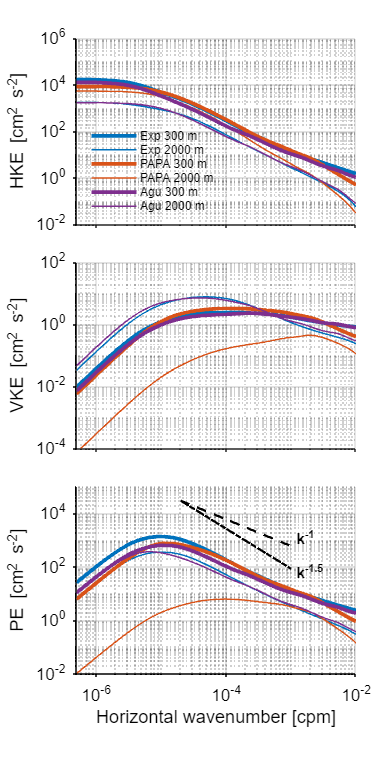

% ========================================================
% Horizontal wavenumber spectra at two depths for 3 stations
% ========================================================

% Clear figure
close all
figure(2); clf

% ========================================================
% User-defined depths [m]
% ========================================================
z1 = -300;
z2 = -2000;
depths = [z1, z2];

% Thicker line for shallow depth, thinner line for deep depth
lineWidths = [2.5, 1.0];

% ========================================================
% Station definitions
% Each station uses one object that contains both:
% - KRadialLog
% - energyAtHorizontalWavenumber(...)
% ========================================================
stations = {'Exp', 'PAPA', 'Agu'};
stationObjects = {igwExp, igwPAPA, igwAgu};

% Consistent color for each station
stationColors = [
    0.0000, 0.4471, 0.7412;   % Exp
    0.8510, 0.3255, 0.0980;   % PAPA
    0.4941, 0.1843, 0.5569    % Agu
];

% ========================================================
% Energy components and plotting metadata
% ========================================================
components = {'HKE', 'VKE', 'PE'};

ylabels = {
    'HKE [cm^2 s^{-2}]', ...
    'VKE [cm^2 s^{-2}]', ...
    'PE [cm^2 s^{-2}]'
};

% Unit conversion factors for plotting
% HKE, PE: m^2/s^2 -> cm^2/s^2
% VKE:     m^2/s^2 -> mm^2/s^2
scaleFactors = [1e3, 1e3, 1e3];

% Y-axis limits for each panel
yLimits = {
    [1e-2, 1e6], ...
    [1e-4, 1e2], ...
    [1e-2, 1e5]
};

% Y-axis ticks for each panel
yTicks = {
    [1e-2, 1, 1e2, 1e4, 1e6], ...
    [1e-4, 1e-2, 1, 1e2], ...
    [1e-2, 1, 1e2, 1e4]
};

% ========================================================
% Create figure with 3 stacked panels
% Increase bottom margin a bit so x tick labels are visible
% tight_subplot arguments:
% tight_subplot(Nh, Nw, gap, marg_h, marg_w)
% marg_h = [bottom top]
% marg_w = [left right]
% ========================================================
[ha, ~] = tight_subplot(3, 1, [0.05 0.04], [0.12 0.05], [0.20 0.07]);

nStations = numel(stations);
nDepths   = numel(depths);

% ========================================================
% Main plotting loop
% ========================================================
for c = 1:numel(components)
    ax = ha(c);
    hold(ax, 'on')

    component   = components{c};
    scaleFactor = scaleFactors(c);

    % ----------------------------------------------------
    % Loop over stations
    % ----------------------------------------------------
    for s = 1:nStations
        stationName = stations{s};
        stationObj  = stationObjects{s};
        thisColor   = stationColors(s, :);

        % Convert radial wavenumber from rad/m to cycles/m
        radialLog = stationObj.KRadialLog / (2*pi);

        % ------------------------------------------------
        % Loop over depths
        % ------------------------------------------------
        for d = 1:nDepths
            z = depths(d);

            % Compute horizontal wavenumber spectrum
            data = stationObj.energyAtHorizontalWavenumber(z, component);

            % Convert units for plotting
            data = data * scaleFactor;

            % Plot spectrum
            loglog(ax, radialLog, data, ...
                'Color', thisColor, ...
                'LineWidth', lineWidths(d));
        end
    end

    % ----------------------------------------------------
    % Add reference power-law slopes only to last panel
    % ----------------------------------------------------
    if c == numel(components)

        % Reference k-range in cycles per meter
        kref = [2e-5, 1e-3];

        % Reference amplitudes chosen visually for this panel
        A1 = 3e4;   % amplitude for k^-1
        A2 = 3e4;     % amplitude for k^-1.5

        ySlope1 = A1 * (kref / kref(1)).^(-1);
        ySlope2 = A2 * (kref / kref(1)).^(-1.5);

        loglog(ax, kref, ySlope1, 'k--', 'LineWidth', 1.5)
        loglog(ax, kref, ySlope2, 'k-.', 'LineWidth', 1.5)

        text(kref(2)*1.15, ySlope1(2)*1.8, 'k^{-1}', ...
            'Parent', ax, ...
            'HorizontalAlignment', 'left', ...
            'VerticalAlignment', 'middle', ...
            'FontSize', 10, ...
            'FontWeight', 'bold', ...
            'Margin', 2)
        
        text(kref(2)*1.15, ySlope2(2)*0.7, 'k^{-1.5}', ...
            'Parent', ax, ...
            'HorizontalAlignment', 'left', ...
            'VerticalAlignment', 'middle', ...
            'FontSize', 10, ...
            'FontWeight', 'bold', ...
            'Margin', 2)
    end

    % ----------------------------------------------------
    % Axis formatting for this panel
    % ----------------------------------------------------
    grid(ax, 'on')
    ax.XScale = 'log';
    ax.YScale = 'log';
    ax.YLim   = yLimits{c};
    ax.YTick  = yTicks{c};

    ylabel(ax, ylabels{c})

    % Show x tick labels only on the bottom panel
    if c < numel(components)
        ax.XTickLabel = [];
    else
        xlabel(ax, 'Horizontal wavenumber [cpm]')
    end
end

% ========================================================
% Global figure formatting
% ========================================================
set(gcf, 'Units', 'centimeters', 'Position', [1, 1, 9, 18])
set(ha, 'FontSize', 11, 'TickDir', 'out', 'Box', 'off')

% Explicitly restore tick labels
for ii = 1:numel(ha)
    ax = ha(ii);

    % Ensure y tick labels are visible
    ax.YTickLabelMode = 'auto';
    ax.YColor = [0 0 0];

    % Only show x tick labels on the last panel
    if ii == numel(ha)
        ax.XTickLabelMode = 'auto';
        ax.XColor = [0 0 0];
    else
        ax.XTickLabel = [];
    end
end

% ========================================================
% Standard legend
% One entry per station/depth combination
% ========================================================
axes(ha(1))

legendHandles = gobjects(nStations*nDepths, 1);
legendEntries = cell(nStations*nDepths, 1);

idx = 0;
for s = 1:nStations
    for d = 1:nDepths
        idx = idx + 1;

        legendHandles(idx) = plot(NaN, NaN, ...
            'Color', stationColors(s,:), ...
            'LineWidth', lineWidths(d));

        legendEntries{idx} = sprintf('%s %d m', ...
            stations{s}, abs(depths(d)));
    end
end

legend(legendHandles, legendEntries, ...
    'Location', 'southwest', ...
    'FontSize', 8, ...
    'Box', 'off')

% ========================================================
% Save figure
% ========================================================
filename = 'PowerSpectrumGM_allStations.png';
exportgraphics(gcf,filename, 'Resolution', 600)

This section computes and plots the horizontal wavenumber spectra of vertical displacement variance for the Exponential, PAPA, and Agulhas cases at two depths. The displacement spectrum is obtained from the modeled potential energy spectrum divided by the local buoyancy frequency squared, η2(kh,z)=PE(kh,z)/N2(z)\eta^2(k_h,z)=PE(k_h,z)/N^2(z)η2(kh�,z)=PE(kh�,z)/N2(z). The resulting spectra are shown on log-log axes, with color indicating station and line thickness indicating depth. Two reference power laws, kh−1k_h^{-1}kh−1� and kh−2k_h^{-2}kh−2�, are overlaid to facilitate comparison with the modeled spectral slopes.

% ========================================================
% Horizontal wavenumber spectra of vertical displacement variance
% eta = sqrt(PE / N^2)
% ========================================================

close all
figure(3); clf

% ========================================================
% User-defined depths [m]
% ========================================================
z1 = -300;
z2 = -2000;
depths = [z1, z2];

% Thicker line for shallow depth, thinner line for deep depth
lineWidths = [2.5, 1.0];

% ========================================================
% Station definitions
% ========================================================
stations = {'Exp', 'PAPA', 'Agu'};
stationObjects = {igwExp, igwPAPA, igwAgu};

% Consistent color for each station
stationColors = [
    0.0000, 0.4471, 0.7412;   % Exp
    0.8510, 0.3255, 0.0980;   % PAPA
    0.4941, 0.1843, 0.5569    % Agu
];

nStations = numel(stations);
nDepths   = numel(depths);

% ========================================================
% Create single panel
% ========================================================
ax = axes;
hold(ax, 'on')

% ========================================================
% Plot vertical displacement spectra for each station/depth
% ========================================================
for s = 1:nStations
    stationObj = stationObjects{s};
    thisColor  = stationColors(s, :);

    % Convert radial wavenumber from rad/m to cycles/m
    radialLog = stationObj.KRadialLog / (2*pi);

    for d = 1:nDepths
        z = depths(d);

        % Potential energy spectrum [m^2 s^-2]
        peSpec = stationObj.energyAtHorizontalWavenumber(z, 'PE');

        % Local buoyancy frequency squared [s^-2]
        N2local = stationObj.N2(z);

        % Vertical displacement variance spectrum [m]
        eta2Spec = (peSpec ./ N2local);

        % Plot
        loglog(ax, radialLog, eta2Spec, ...
            'Color', thisColor, ...
            'LineWidth', lineWidths(d));
    end
end

% ========================================================
% Add reference power-law slopes
% ========================================================
% Choose a reference k-range well inside the plotted domain
kref = [2e-5, 1e-3];

% Reference amplitude chosen to place guide lines in the middle of the panel
A1 = 1.5e5;   % amplitude for k^-1
A2 = 5e4;  % amplitude for k^-2

% Build lines using the left point of kref as anchor
ySlope1 = A1 * (kref / kref(1)).^(-1.2);
ySlope2 = A2 * (kref / kref(1)).^(-1.5);

loglog(ax, kref, ySlope1, 'k--', 'LineWidth', 1.5)
loglog(ax, kref, ySlope2, 'k-.', 'LineWidth', 1.5)

% Optional labels for slope guides
text(kref(2)*0.95, ySlope1(2)*1.2, 'k^{-1.2}', ...
    'HorizontalAlignment', 'right', 'FontSize', 10)
text(kref(2)*0.95, ySlope2(2)*1.2, 'k^{-1.5}', ...
    'HorizontalAlignment', 'right', 'FontSize', 10)

% ========================================================
% Axis formatting
% ========================================================
grid(ax, 'on')
ax.XScale = 'log';
ax.YScale = 'log';
ax.TickDir = 'out';
ax.Box = 'off';
ax.FontSize = 11;

xlabel(ax, 'Horizontal wavenumber [cpm]')
ylabel(ax, '\eta^2 [m^2]')

% Optional axis limits (adjust if needed)
% xlim(ax, [1e-6 1e-2])
ylim(ax, [1e0 1e7])

% ========================================================
% Standard legend
% ========================================================
legendHandles = gobjects(nStations*nDepths + 2, 1);
legendEntries = cell(nStations*nDepths + 2, 1);

idx = 0;
for s = 1:nStations
    for d = 1:nDepths
        idx = idx + 1;

        legendHandles(idx) = plot(NaN, NaN, ...
            'Color', stationColors(s,:), ...
            'LineWidth', lineWidths(d));

        legendEntries{idx} = sprintf('%s %d m', ...
            stations{s}, abs(depths(d)));
    end
end

idx = idx + 1;
legendHandles(idx) = plot(NaN, NaN, 'k--', 'LineWidth', 1);
legendEntries{idx} = 'k^{-1.2}';

idx = idx + 1;
legendHandles(idx) = plot(NaN, NaN, 'k-.', 'LineWidth', 1);
legendEntries{idx} = 'k^{-1.5}';

legend(ax, legendHandles, legendEntries, ...
    'Location', 'southwest', ...
    'FontSize', 8, ...
    'Box', 'off', ...
    'NumColumns', 2)

% ========================================================
% Save figure
% ========================================================
set(gcf, 'Units', 'centimeters', 'Position', [1, 1, 10, 10])
filename = 'PowerSpectrum_VerticalDisplacement_allStations.png';
exportgraphics(gcf, filename, 'Resolution', 600)

### Frequency Spectra

% ========================================================
% Frequency spectra at two depths for 3 stations
% ========================================================

close all
figure(4); clf

% ========================================================
% User-defined depths [m]
% ========================================================
z1 = -300;
z2 = -2000;
depths = [z1, z2];

% Thicker line for shallow depth, thinner line for deep depth
lineWidths = [2.5, 1.0];

% ========================================================
% Station definitions
% ========================================================
stations = {'Exp', 'PAPA', 'Agu'};
stationObjects = {igwExp, igwPAPA, igwAgu};

stationColors = [
    0.0000, 0.4471, 0.7412;   % Exp
    0.8510, 0.3255, 0.0980;   % PAPA
    0.4941, 0.1843, 0.5569    % Agu
];

% Station-specific number of logarithmic bins
nBinsMap = containers.Map( ...
    {'Exp', 'PAPA', 'Agu'}, ...
    [50, 30, 45] );

% ========================================================
% Components and plotting metadata
% ========================================================
components = {'HKE', 'VKE', 'PE'};

ylabels = {
    'HKE [cm^2 s^{-2}]', ...
    'VKE [mm^2 s^{-2}]', ...
    'PE [cm^2 s^{-2}]'
};

% Unit conversion factors
scaleFactors = [1e3, 1e6, 1e3];

yLimits = {
    [3e-4, 5], ...
    [1e-2, 1.1e1], ...
    [1e-4, 1.1]
};

yTicks = {
    [1e-3, 1e-2, 1e-1, 1, 1e1], ...
    [1e-2, 1e-1, 1, 1e1], ...
    [1e-4, 1e-2, 1, 1e1]
};

% ========================================================
% Create figure
% ========================================================
[ha, ~] = tight_subplot(3, 1, [0.05 0.04], [0.12 0.05], [0.20 0.07]);

nStations = numel(stations);
nDepths   = numel(depths);

% ========================================================
% Main plotting loop
% ========================================================
for c = 1:numel(components)
    ax = ha(c);
    hold(ax, 'on')

    component   = components{c};
    scaleFactor = scaleFactors(c);

    for s = 1:nStations
        stationName = stations{s};
        stationObj  = stationObjects{s};
        thisColor   = stationColors(s, :);

        % Station-specific frequency vector
        omegaVector = stationObj.omegaVector;
        freqCPD = omegaVector * (24*3600) / (2*pi);

        % Station-specific number of bins
        nBins = nBinsMap(stationName);

        % Logarithmic bin edges and centers
        binEdges   = logspace(log10(min(freqCPD)), log10(max(freqCPD)), nBins+1);
        binCenters = sqrt(binEdges(1:end-1) .* binEdges(2:end));

        for d = 1:nDepths
            z = depths(d);

            % Raw spectrum as a function of frequency
            data = stationObj.energyAtFrequencies( ...
                z, component, omegaVector=omegaVector);

            % Convert units
            data = data * scaleFactor;

            % Bin-average in log-frequency space
            binnedData = nan(size(binCenters));
            for b = 1:nBins
                idx = freqCPD >= binEdges(b) & freqCPD < binEdges(b+1);
                if any(idx)
                    binnedData(b) = mean(data(idx), 'omitnan');
                end
            end

            % Plot binned spectrum
            loglog(ax, binCenters, binnedData, ...
                'Color', thisColor, ...
                'LineWidth', lineWidths(d));
        end
    end

    % ====================================================
    % Axis formatting
    % ====================================================
    grid(ax, 'on')
    ax.XScale = 'log';
    ax.YScale = 'log';
    ax.YLim   = yLimits{c};
    ax.YTick  = yTicks{c};
    ax.XLim   = [1, 1.1e2];
    ax.XTick  = [1, 1e1, 1e2];

    ylabel(ax, ylabels{c})

    if c < numel(components)
        ax.XTickLabel = [];
    else
        xlabel(ax, 'Frequency [cpd]')
    end
end

% ========================================================
% Global formatting
% ========================================================
set(gcf, 'Units', 'centimeters', 'Position', [1, 1, 9, 18])
set(ha, 'FontSize', 12, 'TickDir', 'out', 'Box', 'off')

for ii = 1:numel(ha)
    ax = ha(ii);
    ax.YTickLabelMode = 'auto';
    ax.YColor = [0 0 0];

    if ii == numel(ha)
        ax.XTickLabelMode = 'auto';
        ax.XColor = [0 0 0];
    else
        ax.XTickLabel = [];
    end
end

% ========================================================
% Standard legend
% ========================================================
axes(ha(1))

legendHandles = gobjects(nStations*nDepths, 1);
legendEntries = cell(nStations*nDepths, 1);

idx = 0;
for s = 1:nStations
    for d = 1:nDepths
        idx = idx + 1;

        legendHandles(idx) = plot(NaN, NaN, ...
            'Color', stationColors(s,:), ...
            'LineWidth', lineWidths(d));

        legendEntries{idx} = sprintf('%s %d m', stations{s}, abs(depths(d)));
    end
end

legend(legendHandles, legendEntries, ...
    'Location', 'northeast', ...
    'FontSize', 8, ...
    'Box', 'off')

% ========================================================
% Save figure
% ========================================================
filename = 'FrequencySpectrum_allStations.png';
exportgraphics(gcf, filename, 'Resolution', 600)

% ========================================================
% Frequency spectra at two depths for 3 stations
% No bin averaging
% ========================================================

close all
figure(4); clf

% ========================================================
% User-defined depths [m]
% ========================================================
z1 = -300;
z2 = -2000;
depths = [z1, z2];

% Thicker line for shallow depth, thinner line for deep depth
lineWidths = [2.5, 1.0];

% ========================================================
% Station definitions
% ========================================================
stations = {'Exp', 'PAPA', 'Agu'};
stationObjects = {igwExp, igwPAPA, igwAgu};

stationColors = [
    0.0000, 0.4471, 0.7412;   % Exp
    0.8510, 0.3255, 0.0980;   % PAPA
    0.4941, 0.1843, 0.5569    % Agu
];

% ========================================================
% Components and plotting metadata
% ========================================================
components = {'HKE', 'VKE', 'PE'};

ylabels = {
    'HKE [cm^2 s^{-2}]', ...
    'VKE [cm^2 s^{-2}]', ...
    'PE [cm^2 s^{-2}]'
};

% Unit conversion factors
scaleFactors = [1e3, 1e3, 1e3];

yLimits = {
    [3e-4, 1e2], ...
    [1e-4, 2e-2], ...
    [5e-4, 1.1]
};

yTicks = {
    [1e-3, 1e-2, 1e-1, 1, 1e1], ...
    [1e-4, 1e-3, 1e-2], ...
    [1e-3, 1e-2, 1e-1, 1, 1e1]
};

% ========================================================
% Create figure
% ========================================================
[ha, ~] = tight_subplot(3, 1, [0.05 0.04], [0.12 0.05], [0.20 0.07]);

nStations = numel(stations);
nDepths   = numel(depths);

% ========================================================
% Main plotting loop
% ========================================================
for c = 1:numel(components)
    ax = ha(c);
    hold(ax, 'on')

    component   = components{c};
    scaleFactor = scaleFactors(c);

    for s = 1:nStations
        stationObj = stationObjects{s};
        thisColor  = stationColors(s, :);

        % Station-specific frequency vector
        omegaVector = stationObj.omegaVector;
        freqCPD = omegaVector * (24*3600) / (2*pi);

        for d = 1:nDepths
            z = depths(d);

            % Raw spectrum as a function of frequency
            data = stationObj.energyAtFrequencies( ...
                z, component, omegaVector=omegaVector);

            % Convert units
            data = data * scaleFactor;

            % Plot raw spectrum
            loglog(ax, freqCPD, data, ...
                'Color', thisColor, ...
                'LineWidth', lineWidths(d));
        end
    end

    % ====================================================
    % Axis formatting
    % ====================================================
    grid(ax, 'on')
    ax.XScale = 'log';
    ax.YScale = 'log';
    ax.YLim   = yLimits{c};
    ax.YTick  = yTicks{c};
    ax.XLim   = [1, 1.1e2];
    ax.XTick  = [1, 1e1, 1e2];

    ylabel(ax, ylabels{c})

    if c < numel(components)
        ax.XTickLabel = [];
    else
        xlabel(ax, 'Frequency [cpd]')
    end
end

% ========================================================
% Global formatting
% ========================================================
set(gcf, 'Units', 'centimeters', 'Position', [1, 1, 9, 18])
set(ha, 'FontSize', 12, 'TickDir', 'out', 'Box', 'off')

for ii = 1:numel(ha)
    ax = ha(ii);
    ax.YTickLabelMode = 'auto';
    ax.YColor = [0 0 0];

    if ii == numel(ha)
        ax.XTickLabelMode = 'auto';
        ax.XColor = [0 0 0];
    else
        ax.XTickLabel = [];
    end
end

% ========================================================
% Standard legend
% ========================================================
axes(ha(1))

legendHandles = gobjects(nStations*nDepths, 1);
legendEntries = cell(nStations*nDepths, 1);

idx = 0;
for s = 1:nStations
    for d = 1:nDepths
        idx = idx + 1;

        legendHandles(idx) = plot(NaN, NaN, ...
            'Color', stationColors(s,:), ...
            'LineWidth', lineWidths(d));

        legendEntries{idx} = sprintf('%s %d m', stations{s}, abs(depths(d)));
    end
end

legend(legendHandles, legendEntries, ...
    'Location', 'northeast', ...
    'FontSize', 8, ...
    'Box', 'off')

% ========================================================
% Save figure
% ========================================================
filename = 'FrequencySpectrum_allStations_noBinning.png';
exportgraphics(gcf, filename, 'Resolution', 600)

### Hydrostatic vs non hydrostatic map

% --- Percent field ---
data_pct = abs((igwExp.h(:,1) - igwExp.h) ./ igwExp.h) * 100;

% Avoid log10(0)
data_pct(data_pct <= 0) = NaN;

X = log10(igwExp.KRadialLog);
Y = igwExp.j;

% --- Choose displayed color range in % ---
vmin = 1;
vmax = 1e4;

% Clip data to plotted range
data_pct(data_pct < vmin) = vmin;
data_pct(data_pct > vmax) = vmax;

% --- Transform to log10 space for plotting ---
data_log = log10(data_pct);

% --- Log-spaced filled contour levels ---
nlev = 20;
levels_pct = logspace(log10(vmin), log10(vmax), nlev);
levels_log = log10(levels_pct);

figure

% --- Filled contours in log space ---
contourf(X, Y, data_log, levels_log, 'LineColor', 'none')
colormap(cmocean('deep'))

% --- Colorbar in %, positioned in log space ---
cb = colorbar;
cb.Title.String = '%';
cb.Title.FontWeight = 'bold';
cb.FontSize = 14;

tick_pct = [1 10 100 1000 10000];
cb.Ticks = log10(tick_pct);
cb.TickLabels = string(tick_pct);

hold on
omegaIner= igwExp.omega./igwExp.f0;

hold on

% --- Dashed contour lines at 10%, 50%, 100% ---
levels_line_pct = [10 50 100];
levels_line_log = log10(levels_line_pct);

contour(X, Y, data_log, levels_line_log, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'LineStyle', '--');

% --- Thin gray contours for omegaIner ---
omega_levels = [1.1 1.5 2.0 4.0 10 20 30];

[Cg,hg] = contour(X, Y, omegaIner, omega_levels, ...
    'LineColor', [0 0 0], ...
    'LineWidth', 0.75);



% --- Force color scaling again, just in case ---
clim([log10(vmin) log10(vmax)])

% --- Dashed contour lines at 10%, 50%, 100% ---
levels_line_pct = [10 50 100];
levels_line_log = log10(levels_line_pct);

contour(X, Y, data_log, levels_line_log, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'LineStyle', '--');

% --- Axis formatting ---
xticks(log10(2*pi./[1e5 1e4 1e3 1e2]))
xticklabels({'100 km','10 km', '1 km', '100 m'})

xlabel('Wavelength')
ylabel('j')

xlim([log10(2*pi/1e5), log10(2*pi/1e2)])
set(gca, 'YScale', 'log')

set(gca, 'FontSize', 14, 'LineWidth', 1.2)
set(gcf, 'Color', 'w')


%exportgraphics(gcf, 'non-HydroContours_logColorMap.png', 'Resolution', 600)

% --- Manually place one label for each gray contour ---
disp('Click once for each gray contour label, in this order:')
disp('1.1f, 1.5f, 2.0f, 4.0f, 10.0f, 20.0f')

[xlab, ylab] = ginput(numel(omega_levels));


%rot = [80 80 80 80 80 80 80];
rot = [45 45 45 45 45 45 45];

for i = 1:numel(omega_levels)
    text(xlab(i), ylab(i), sprintf('%.1ff', omega_levels(i)), ...
        'Color', [0 0 0], ...
        'FontSize', 10, ...
        'FontWeight', 'bold', ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'middle', ...
        'Rotation', rot(i));
end

%% Percent difference field

data_pct = abs((igwExp.h(:,1) - igwExp.h) ./ igwExp.h) * 100;

X = log10(igwExp.KRadialLog);
Y = igwExp.j;

vmin = 0;
vmax = 100;

omegaIner = igwExp.omega ./ igwExp.f0;


%% Figure setup

figure
set(gcf, 'Color', 'w')

pcolor(X, Y, data_pct)
shading flat
hold on

clim([vmin vmax])


%% Colormap

n = 256;
cmap = cmocean('tempo', n);

% Remove very light and very dark extremes
cmap = cmap(round(0.05*n):round(0.75*n), :);

% Mild gamma correction
gamma = 1;
idx = round(linspace(1, size(cmap,1), n).^gamma);
idx = max(1, min(size(cmap,1), idx));

cmap = cmap(idx, :);

colormap(cmap)


%% Colorbar

cb = colorbar;
cb.Title.String = '%';
cb.Title.FontWeight = 'bold';
cb.FontSize = 12;
cb.FontWeight = 'normal';
cb.LineWidth = 1.5;
cb.TickDirection = 'out';

% omega/f contours
omega_levels = [1.1 1.5 2.0 4.0 10 20 30];

contour(X, Y, omegaIner, omega_levels, ...
    'LineColor', [0 0 0], ...
    'LineWidth', 0.75);


%% Axis formatting

xticks(log10(2*pi ./ [1e5 1e4 1e3 1e2]))
xticklabels({'100 km', '10 km', '1 km', '100 m'})

xlabel('Wavelength', 'FontWeight', 'bold', 'FontSize', 12)
ylabel('j', 'FontWeight', 'bold', 'FontSize', 12)

xlim([log10(2*pi/1e5), log10(2*pi/1e2)])

ax = gca;
ax.YScale = 'log';
ax.FontSize = 12;          % axis tick label font size
ax.FontWeight = 'normal';  % axis tick label weight
ax.Box = 'on';
ax.TickDir = 'in';
ax.LineWidth = 1.5;
ax.TickLength = [0.015 0.015];
ax.Layer = 'top';

ax.XMinorTick = 'on';
ax.YMinorTick = 'on';

%---
%% Regime labels

text(0.04, 0.94, 'hydrostatic', ...
    'Units', 'normalized', ...
    'FontSize', 10, ...
    'FontWeight', 'bold', ...
    'Color', 'k', ...
    'BackgroundColor', 'w', ...
    'Margin', 4, ...
    'HorizontalAlignment', 'left', ...
    'VerticalAlignment', 'top');

text(0.96, 0.06, 'non-hydrostatic', ...
    'Units', 'normalized', ...
    'FontSize', 10, ...
    'FontWeight', 'bold', ...
    'Color', 'k', ...
    'BackgroundColor', 'w', ...
    'Margin', 4, ...
    'HorizontalAlignment', 'right', ...
    'VerticalAlignment', 'bottom');



%% Manual labels for omega/f contours

disp('Click once for each black contour label, in this order:')
disp('1.1f, 1.5f, 2.0f, 4.0f, 10.0f, 20.0f, 30.0f')

[xlab, ylab] = ginput(numel(omega_levels));

rot = 45 * ones(size(omega_levels));

for i = 1:numel(omega_levels)
    text(xlab(i), ylab(i), sprintf('%.1ff', omega_levels(i)), ...
        'Color', [0 0 0], ...
        'FontSize', 10, ...
        'FontWeight', 'bold', ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'middle', ...
        'Rotation', rot(i));
end


%% Export

exportgraphics(gcf, 'nonHydroContours_pcolor.png', 'Resolution', 600)